# Seminar 11 - Change detection methods

**Authors:** Ing. David Vošahlík, prof. Ing. Vladimír Havlena, CSc.

## Introduction

Change detection will be studied in this seminar. Change detection is important for many systems. It is used e.g. in health monitoring systems (battery health monitoring, airplane engine health monitoring, vehicle turbocharger health monitoring, ...). One of the most used priniciple in the change detection methods is likelihood ratio (FMA, GMA and many other algorithms are based on this). This approach requires two disjunctive hypothesis with probabilities $p_1$and $p_2$. The likelihood ratio is then computed as

$g\left(Y^n \right)=1$for $\frac{p_1 \left(Y^n \right)}{p_0 \left(Y^n \right)}\ge \lambda_{\alpha }$

$g\left(Y^n \right)=0$ for $\frac{p_1 \left(Y^n \right)}{p_0 \left(Y^n \right)}<\;\lambda_{\alpha }$

where the $g\left(Y^n \right)$ is critical function of the data $Y^n$ (decides if the change occured), $\lambda_{\alpha }$ is constant that is computed based on significance level $\alpha$. Further details about theory are to be find in the lectures.

## SLR, GMA and FMA algorithms

In this section sequential likelihood ratio (SLR), geometric moving average (GMA) and finite moving average (FMA) methods will be studied and compared. For this purpose we will take simple mean change in normal distribution. Up to time $T_c$ the distribution will have mean $\mu_0$. After that it will change to $\mu_1 \ldotp$ Your task will be

- Implement SLR method

- Implement GMA method

- Implement FMA method 

- Compare the results - choose some suitable metrics for it e.g. delay of detection, false positive detections,...

Tune different parameters and observe the algorithm behavior

**SLR**

- $\alpha$ parameter

- $\beta \;$parameter

**FMA**

- $\lambda$ parameter

- Lenght of the window

**GMA**

- $\lambda$ parameter

- $\varphi$ parameter

### SLR

Implement into the prepared script the SLR method in the logarithmic version (add the log ratio to the current statistics instead of the multiplication).

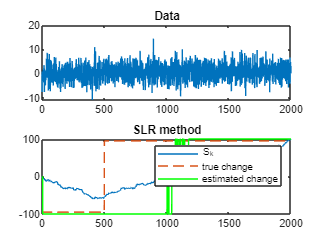

T = 2000;   % sample size
Tc = 500;   % change time
%
mu0 = 0;
mu1 = 0.7;
sigma = 3; % use 1 - 3
%
rng('default');
rng(2); % to allow algorithm comparison
D0 = mu0 + sigma*randn(T+1,1);
D1 = mu1 + sigma*randn(T+1,1);
D = [D0(1:Tc); D1(Tc+1:T+1)]; %data with change of its mean value at Tc

% setup the algorithm parameters
alpha = 0.05;
beta = 0.05;

a = log(beta/(1 - alpha));
b = log((1- beta)/alpha);

% evaluate Sk statistics.
Sk = zeros(T+1,1);
g = nan(T+1,1);
Sk(1) = log(gauss(D(1),mu1,sigma)/gauss(D(1),mu0,sigma));
for t=2:T+1
    % S(t) = S(t-1) + s(t)
    Sk(t) = Sk(t-1)+ log(gauss(D(t),mu1,sigma)/gauss(D(t),mu0,sigma));
    if Sk(t) >= b
        g(t) = 1;
    elseif Sk(t) <= a
        g(t) = -1;
    else % indefinite region
        g(t) = 0;
    end
    % S(t) = S(t) - s(t-K)
%     if t > K
%         Sk(t) = Sk(t) - log(gauss(D(t-K),mu1,sigma)/gauss(D(t-K),mu0,sigma));
%     end
end
figure
subplot(2,1,1)
plot(0:T, D);
title('Data')
subplot(2,1,2)
plot(0:T,Sk, 0:T, [-95*ones(1,numel(0:Tc)) 95*ones(1, numel(Tc:T) - 1)], '--', 0:T, g*100, 'g');
legend('S_k', 'true change', 'estimated change');
title('SLR method')


g_SRL = g;

### FMA algorithm

Implement into the prepared script the FMA method

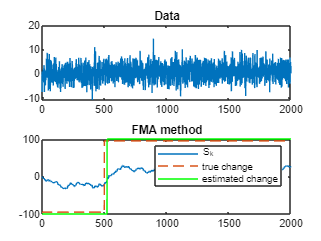

% setup the FMA algorithm parameters
lambda = -10;
K = 200;
% evaluate Sk statistics.
Sk = zeros(T+1,1);
g = nan(T+1,1);
Sk(1) = log(gauss(D(1),mu1,sigma)/gauss(D(1),mu0,sigma));
for t=2:T+1
    % S(t) = S(t-1) + s(t)
    Sk(t) = Sk(t-1)+ log(gauss(D(t),mu1,sigma)/gauss(D(t),mu0,sigma));
    
%     S(t) = S(t) - s(t-K)
    if t > K
        Sk(t) = Sk(t) - log(gauss(D(t-K),mu1,sigma)/gauss(D(t-K),mu0,sigma));
        if Sk(t) >= lambda
            g(t) = 1;
        else
            g(t) = -1;
        end
    else
        g(t) = -1;
    end
    
    
end
figure
subplot(2,1,1)
plot(0:T, D);
title('Data')
subplot(2,1,2)
plot(0:T,Sk, 0:T, [-95*ones(1,numel(0:Tc)) 95*ones(1, numel(Tc:T) - 1)], '--', 0:T, g*100, 'g');
legend('S_k', 'true change', 'estimated change');
title('FMA method')


g_FMA = g;

### GMA algorithm

Implement into the prepared script the GMA method

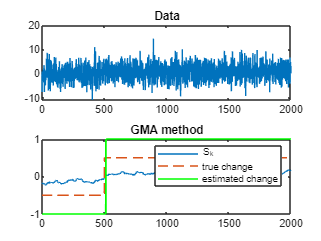

% setup the FMA algorithm parameters
phi = 0.99;
lambda = 0.01;
% evaluate Sk statistics.
Sk = zeros(T+1,1);
g = nan(T+1,1);
Sk(1) = log(gauss(D(1),mu1,sigma)/gauss(D(1),mu0,sigma));
for t=2:T+1
    % S(t) = phi*S(t-1) + (1 - phi)*s(t)
    Sk(t) = phi*Sk(t-1)+ (1 - phi)*log(gauss(D(t),mu1,sigma)/gauss(D(t),mu0,sigma));
    
    if Sk(t) >= lambda
        g(t) = 1;
    else
        g(t) = -1;
    end
    
end
figure
subplot(2,1,1)
plot(0:T, D);
title('Data')
subplot(2,1,2)
plot(0:T,Sk, 0:T, [-.5*ones(1,numel(0:Tc)) .5*ones(1, numel(Tc:T) - 1)], '--', 0:T, g, 'g');
legend('S_k', 'true change', 'estimated change');
title('GMA method')


g_GMA = g;


### Comparison of the methods

The comparison criteria would be (feel free to add some missing criteria)

- delay to first detection of change

- number of samples that are false negative (after the change). The indefinite samples in SLR method will not be counted.

i_SRL = find(g_SRL(Tc:T) > 0, 1) + Tc - 1;
error_SLR = sum(g_SRL(Tc:i_SRL) < 0) + ...  % delay to the first sample where the change is detected
    sum(g_SRL(1:Tc) > 0) + ...              % number of false positive
    sum(g_SRL(i_SRL:T) < 0);                % number of false negative

i_FMA = find(g_FMA(Tc:T) > 0, 1) + Tc - 1;
error_FMA = sum(g_FMA(Tc:i_FMA) < 0) + ...  % delay to the first sample where the change is detected
    sum(g_FMA(1:Tc) > 0) + ...              % number of false positive
    sum(g_FMA(i_FMA:T) < 0);                % number of false negative

i_GMA = find(g_GMA(Tc:T) > 0, 1) + Tc - 1;
error_GMA = sum(g_GMA(Tc:i_GMA) < 0) + ...  % delay to the first sample where the change is detected
    sum(g_GMA(1:Tc) > 0) + ...              % number of false positive
    sum(g_GMA(i_GMA:T) < 0);                % number of false negative
disp(['Sample error of SRL is ' num2str(error_SLR) ', of FMA ' num2str(error_FMA) ' and of GMA ' num2str(error_GMA)]);

Sample error of SRL is 539, of FMA 24 and of GMA 15


### Appendix

Here are some handy functions that can be used for your purposes.

function varargout = gauss(x, mi, sig2, plot95, varargin)
%GAUSS Gaussian bell-function. 
% P = GAUSS(x,mi,sig2) calculate probability P of value(s) x in a normal
% distribution defined by mean value mi and variance sig2
%
% GAUSS(x,mi,sig,...) plot gaussian bell-function defined by mean mi and
% variance sig2 and plot a marker at position(s) x (put '[]' for none). Plot options can be
% specified. Example: gauss([-sqrt(2),sqrt(2)],0,2,'Linewidth',2,'Color','b');

% Matisko 2010, Dostal 2013, Hauser 2019

if nargout == 1
    
    % calc probability of point(s) x
    varargout{1} = (sqrt(2*pi*sig2))^(-1) .* exp( -(x - mi).^2 ./ sig2 / 2 );
    
elseif nargout == 0 
    % plot gaussian 
    
    % number of points in graph
    M = 50; 
    sig = sqrt(sig2);
    minm = (mi-4*sig);
    maxm = (mi+4*sig);
    step = (maxm - minm)/M;    
    s = minm+step:step:maxm;        
    gs = gauss(s,mi,sig2);
    gx = gauss(x,mi,sig2);
    
    ishld = ishold;    
    %plot
    if nargin == 4 
       
        plot(s,gs,'DisplayName',['N(',num2str(mi),',',num2str(sig2),')'],'Linewidth',2);  
        hold on
        plot([mi mi],[max(gs), 0],'DisplayName',['\mu=',num2str(mi)],'Linewidth',1.3);
        if plot95
                            % implement the 95% confindece interval
        else
            plot([mi-sig, mi+sig],[gauss(mi-sig,mi,sig2), gauss(mi+sig,mi,sig2)],'DisplayName',['\sigma=',num2str(sig)],'Linewidth',1.3);
        end
        
        stem(x,gx,'r');
        
        grid on
        if ~ishld
            hold off
        end       
        
    elseif nargin > 4       
        
        plot(s,gs,'DisplayName',['N(',num2str(mi),',',num2str(sig2),')'],varargin{:}); 
        hold on
        stem(x,gx,'r');   
        
        grid on     
        if ~ishld
            hold off
        end       
        
    else
        error('Wrong number of input parameters. See ''help gauss''');
    end
    legend show
else
    error('Wrong number of output parameters. See ''help gauss''');
end
end